Lab 7. Event selection optimization You and your lab partner should pick *different* pT (transverse momentum) samples (one uses low-pT sampels and the other use high-pT samples) for this lab. In each pT sample, there are dedicated training samples for event selection optimization. All studies should be carried out by normalizing Higgs and QCD samples in each pT sample to given expected yields accordingly (See Dataset descriptions).

clear all; close all; clc;
tic;
h5disp("higgs_100000_pt_250_500.h5")

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


higg1 = h5read("higgs_100000_pt_250_500.h5",'/higgs_100000_pt_250_500');
h5disp("higgs_100000_pt_250_500.h5")

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


qcd1 = h5read("qcd_100000_pt_250_500.h5",'/qcd_100000_pt_250_500');

Make a stacked histogram plot for the feature variable: mass

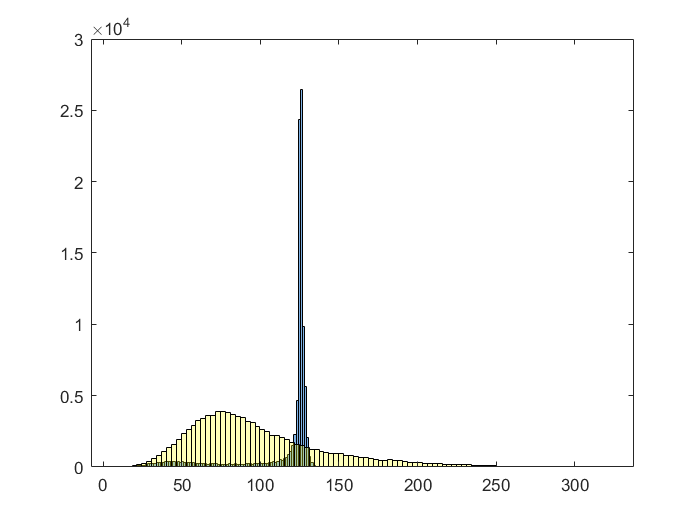

hInvariantMass = higg1(4,:);
histogram(hInvariantMass,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
qInvariantMass = qcd1(4,:);
histogram(qInvariantMass,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

hInvarAvg = mean(hInvariantMass)

hInvarAvg = 114.8924

hInvarSTD = std(hInvariantMass)

hInvarSTD = 25.3511

qInvarAvg = mean(qInvariantMass)

qInvarAvg = 97.7380

qInvarSTD = std(qInvariantMass)

qInvarSTD = 43.4929

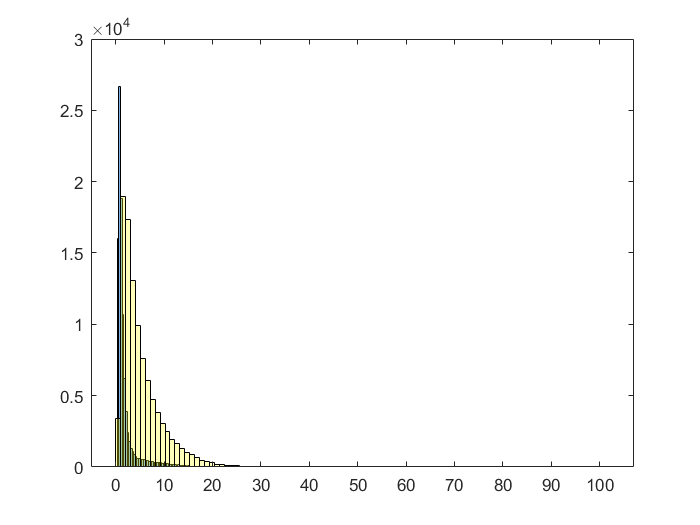

h3to2pointECFratio = higg1(7,:);
histogram(h3to2pointECFratio,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
q3to2pointECFratio = qcd1(7,:);
histogram(q3to2pointECFratio,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

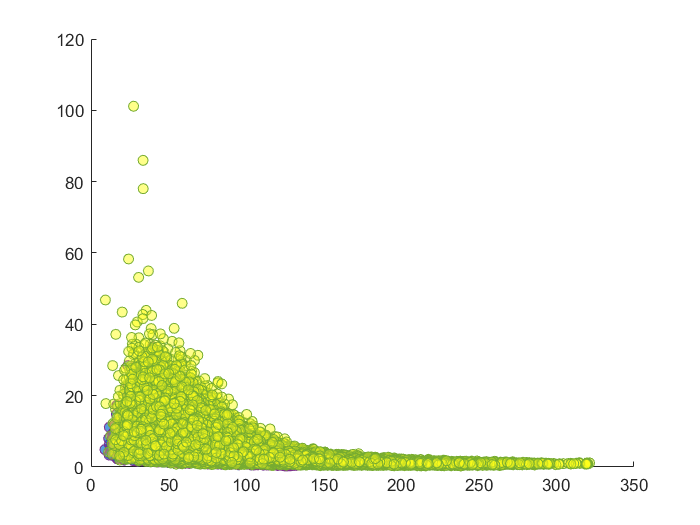

hold on;
scatter(hInvariantMass,h3to2pointECFratio,'MarkerFaceColor',[0,.4,.8],'MarkerFaceAlpha',0.3)
scatter(qInvariantMass,q3to2pointECFratio,'MarkerFaceColor',[1,1,.1],'MarkerFaceAlpha',0.3)

- Evaluate expected significance without any event selection.

- Use Poisson statistics for significance calculation

- Compare your number of NHiggs/(√NQCD)NHiggs/(NQCD). If they are equivalent, explain your findings.

toc;

Elapsed time is 8.872376 seconds.
